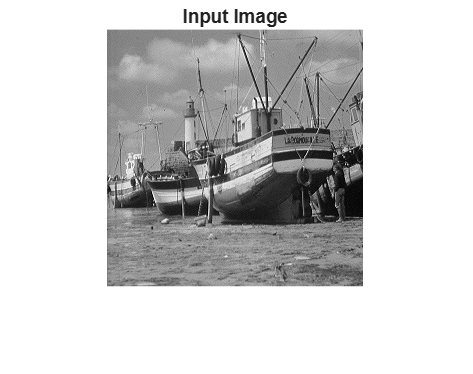

clc;
clear;
close all;

[file, path] = uigetfile({'*.jpg;*.jpeg;*.png;*.bmp;*.tif', ...
    'Image Files (*.jpg, *.jpeg, *.png, *.bmp, *.tif)'}, ...
    'Select an Image');

if isequal(file, 0)
    disp('No image selected.');
    return;
end

img = imread(fullfile(path, file));

figure;
imshow(img);
title('Input Image');


noiseFeatures = extractNoiseFeatures(img);

disp(' ');

disp('Extracted Noise Features:');

Extracted Noise Features:


disp('-------------------------');

-------------------------



for i = 1:length(noiseFeatures)
    fprintf('Feature %d = %.6f\n', i, noiseFeatures(i));
end

Feature 1 = 11.001236
Feature 2 = 15.486853
Feature 3 = -0.079231
Feature 4 = 8.751816
Feature 5 = 25.408997
Feature 6 = 43.173997
Feature 7 = -0.227261
Feature 8 = 13.362178
Feature 9 = 21.828400
Feature 10 = 33.122994
Feature 11 = -0.689203
Feature 12 = 9.177489
Feature 13 = 0.799811



fprintf('\nTotal number of features = %d\n', length(noiseFeatures));


Total number of features = 13



function noiseFeatures = extractNoiseFeatures(img)

    if size(img, 3) == 3
        gray = rgb2gray(img);
    else
        gray = img;
    end

    gray = double(gray);

    kernels = {
        [-1  2 -1;
          2 -4  2;
         -1  2 -1] / 4, ...
        
        [0  0  0;
         1 -2  1;
         0  0  0], ...
        
        [0  1  0;
         0 -2  0;
         0  1  0]
    };

    stats = [];

    for k = 1:numel(kernels)

        residual = conv2(gray, kernels{k}, 'same');

        r = residual(:);

        featureMean = mean(abs(r));
        featureStd = std(r);
        featureSkewness = skewness(r);
        featureKurtosis = kurtosis(r);

        stats = [stats, ...
            featureMean, ...
            featureStd, ...
            featureSkewness, ...
            featureKurtosis];

    end

    residual = conv2(gray, kernels{1}, 'same');

    blockSize = 16;

    [h, w] = size(residual);

    hB = floor(h / blockSize);
    wB = floor(w / blockSize);

    blockVars = zeros(hB, wB);

    for i = 1:hB

        for j = 1:wB

            rowStart = (i-1)*blockSize + 1;
            rowEnd = i*blockSize;

            colStart = (j-1)*blockSize + 1;
            colEnd = j*blockSize;

            block = residual(rowStart:rowEnd, colStart:colEnd);

            blockVars(i,j) = var(block(:));

        end

    end

    if isempty(blockVars)
        noiseInconsistency = 0;
    else
        noiseInconsistency = std(blockVars(:)) / ...
            (mean(blockVars(:)) + eps);
    end

    noiseFeatures = [stats, noiseInconsistency];

end